alphas = logspace(log10(2e-6),log10(5e-2), 30)

alphas =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0008    0.0011    0.0015    0.0022    0.0031    0.0043    0.0062    0.0087    0.0124    0.0175    0.0249    0.0353    0.0500


disp(alphas(1))   % Should show 2.0000e-06

   2.0000e-06



disp(alphas(end)) % Should show 0.0500 (which is 5e-2)

    0.0500



% Now prepare the buffers
rho = zeros(length(alphas), 1);
eta = zeros(length(alphas), 1);

matrix_size = [301, 351, 128];
voxel_size = [0.9766, 0.9766, 2.344];
smv = 2;

maski = niftiread("E:\msc_data\sc_qsm\final_gauss_sims\masks\only_sc_crop.nii.gz");

S = SMV_kernel(matrix_size, voxel_size, smv);
M1 = SMV(maski, matrix_size, voxel_size, smv)>0.999;

A  = @(x) M1 .* ifftn(S .* fftn(x));
Ah = @(x) ifftn(S .* fftn(M1 .* x));

% Loading frequency map phantom adata
iFreq = niftiread("E:\msc_data\sc_qsm\final_gauss_sims\November_2025\mrsim_outputs\custom_params_snr_74\fm_tests\test2_msk_apply\B0.nii");

% Loading in-vivo data
iFreq_invivo = niftiread("E:\msc_data\sc_qsm\neuropoly_data\chi_003\qsm_processing\2nd_3D_meGRE\fm_tests\test2_msk_apply\B0.nii");

maski_invivo = niftiread("E:\msc_data\sc_qsm\neuropoly_data\chi_003\qsm_processing\2nd_3D_meGRE\chi_003_m2_sc_msk.nii.gz");

mat_invivo = [384, 384, 16];
vox_invivo = [0.4427, 0.4427, 5];
rho_invivo = zeros(length(alphas), 1);
eta_invivo = zeros(length(alphas), 1);

S_invivo = SMV_kernel(mat_invivo, vox_invivo, smv);
M1_invivo = SMV(maski_invivo, mat_invivo, vox_invivo, smv)>0.999;

A_invivo  = @(x2) M1_invivo .* ifftn(S_invivo .* fftn(x2));
Ah_invivo = @(x2) ifftn(S_invivo .* fftn(M1_invivo .* x2));

% Loop over alphas
for k = 1:length(alphas)
    alpha = alphas(k);

    curr_RDF = my_resharp(iFreq_invivo, maski_invivo, mat_invivo, vox_invivo, smv, alpha);
    
    r = Ah_invivo(curr_RDF) - A_invivo(iFreq_invivo); % residual
    rho_invivo(k) = norm(r(:), 2);

    % --- regularization term ---
    eta_invivo(k) = norm(curr_RDF(:), 2);

    fprintf('Finished alpha %d/%d\n', k, length(alphas));

end

Finished alpha 1/30
Finished alpha 2/30
Finished alpha 3/30
Finished alpha 4/30
Finished alpha 5/30
Finished alpha 6/30
Finished alpha 7/30
Finished alpha 8/30
Finished alpha 9/30
Finished alpha 10/30
Finished alpha 11/30
Finished alpha 12/30
Finished alpha 13/30
Finished alpha 14/30
Finished alpha 15/30
Finished alpha 16/30
Finished alpha 17/30
Finished alpha 18/30
Finished alpha 19/30
Finished alpha 20/30
Finished alpha 21/30
Finished alpha 22/30
Finished alpha 23/30
Finished alpha 24/30
Finished alpha 25/30
Finished alpha 26/30
Finished alpha 27/30
Finished alpha 28/30
Finished alpha 29/30
Finished alpha 30/30


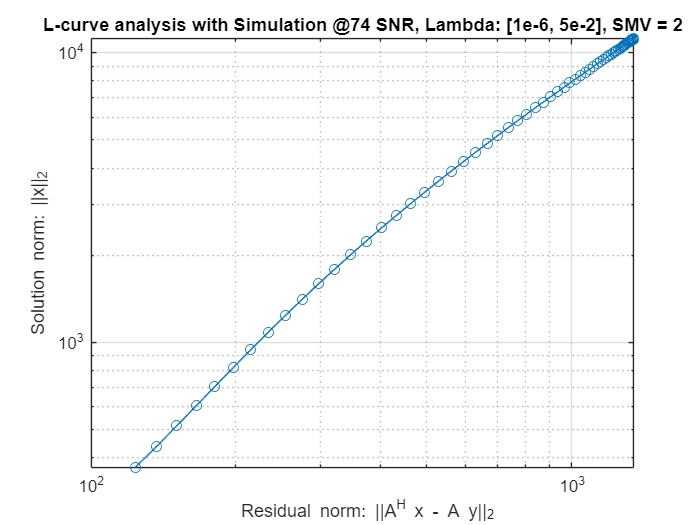

loglog(rho, eta, '-o')
xlabel('Residual norm: ||A^H x - A y||_2')
ylabel('Solution norm: ||x||_2')
title('L-curve analysis with Simulation @74 SNR, Lambda: [1e-6, 5e-2], SMV = 2')
grid on

x = log(rho);
y = log(eta);

dx = gradient(x);
dy = gradient(y);
ddx = gradient(dx);
ddy = gradient(dy);

curvature = abs(dx .* ddy - dy .* ddx) ./ (dx.^2 + dy.^2).^(3/2);

[~, idx] = max(curvature);
alpha_opt = alphas(idx)

alpha_opt = 0.0147

% Let's see the fourier transform of our data?

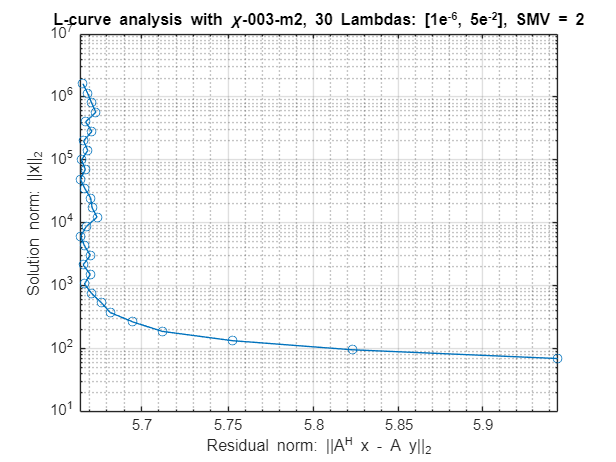

% Trying w invivo
loglog(rho_invivo, eta_invivo, '-o')
xlabel('Residual norm: ||A^H x - A y||_2')
ylabel('Solution norm: ||x||_2')
title('L-curve analysis with \chi-003-m2, 30 Lambdas: [1e^{-6}, 5e^{-2}], SMV = 2')
grid on

x = log(rho_invivo);
y = log(eta_invivo);

dx = gradient(x);
dy = gradient(y);
ddx = gradient(dx);
ddy = gradient(dy);

curvature = abs(dx .* ddy - dy .* ddx) ./ (dx.^2 + dy.^2).^(3/2);

[~, idx] = max(curvature);
alpha_opt = alphas(idx)

alpha_opt = 0.0353